# Resolución de problemas utilizando el método simplex matricial

## Descripción del método

## Parámetros iniciales para las ejemplos

### Problema 1

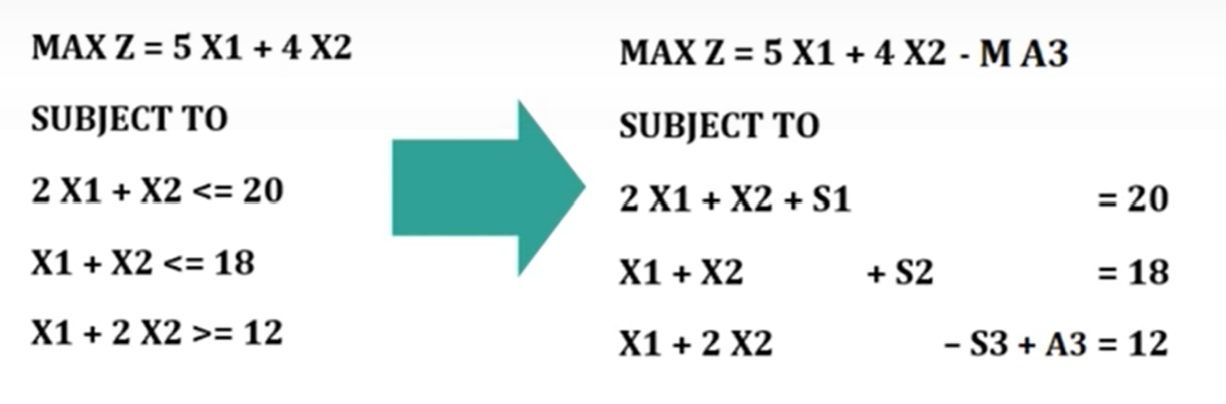

En este ejemplo se maximizará la función $Z = 5X_1 + 4X_2 - MA_3$. Como se podrá ver en la imagen anterior, se tienen que hacer cambios en la ecuación a maximizar, así como en las restricciones a las que está sujeta para poder hacer uso del método *simplex *matricial. Se podrá observar que las restricciones se convierten de desigualdades a igualdades. 

A1 = [2,1 ; 1,1 ; 1,2];
c1 = [5,4];
[~, n1] = size(A1);
% Para convertir las restricciones en igualdades se utilizaron variables de holgura,
% artificiales y de exceso. Al modificarse el vector C y la matriz A, se
% concatenan los nuevos valores a las asignaciones viejas de A y C. 
% Los vectores quedan de la siguiente forma:

M1 = 10000;

c1 = [c1, [0, 0, 0, -M1]]; % Coeficientes de la ecuación a maximizar
A1 = [ A1(1,:), [1,0,0,0]; A1(2,:) , [0,1,0,0]; A1(3,:), [0,0,-1,1]]; % Coeficientes de las restricciones
b1 = [20 , 18 , 12]; % Los resultados de las restricciones
Bx1=[3,4,6]; % Matriz identidad

### Problema 2

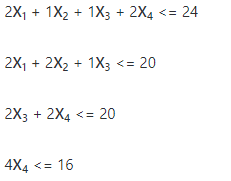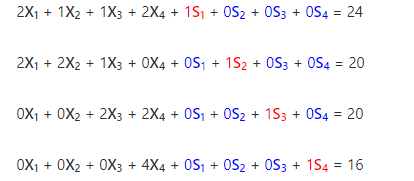

Se maximizará la función $Z =  20,000 X_1 + 20,000 X_2 + 20,000 X_3 + 20,000 X_4$ sujeto a una serie de restricciones mostradas en la imagen anterior. Cambios similares a los raelizados en el problema 1 se utilizaran para poder aplicar el método *simplex *matricial.

c2 = [20000,20000,20000,20000];
A2 = [2,1,1,2;2,2,1,0;0,0,2,2;0,0,0,4];
[~, n2] = size(A2);

% Se asignan las variables de holgura y exceso y se concatenan a C y A.
% Nótese que para el ejemplo 2 no se requirió el uso de variables
% artificiales.
c2=[c2, [0, 0, 0, 0]]; % Coeficientes de la ecuación a maximizar
A2=[A2(1,:),[1,0,0,0] ; A2(2,:),[0,1,0,0] ; A2(3,:),[0,0,1,0]; A2(4,:),[0,0,0,1]]; % Coeficientes de las restricciones
b2=[24, 20, 20, 16]; % Los resultados de las restricciones

Bx2=[5,6,7,8]; % Matriz identidad

### Problema 3 (minimización)

A diferencia de lo realizado en el problema 1 y problema 2, aquí se busca minimizar la función, por lo que se necesita una pequeña modificación. Minimizar una función F es equivalente a maximizar -F. Por lo que estaremos maximizando $-Z = -2 X_1 + X_2$.

c3 = [-2,1];
A3 = [2,3;1,1];
[~, n3] = size(A3);
% Se asignan las variables de holgura y exceso y se concatenan a C y A.
% Nótese que para el ejemplo 3 no se requirió el uso de variables
% artificiales.
c3 = [c3, [0, 0]]; % Coeficientes de la ecuación a maximizar
A3 = [A3(1,:),[1,0] ; A3(2,:),[0,1]]; % Coeficientes de las restricciones
b3 = [10,6]; % Los resultados de las restricciones

Bx3=[3,4]; % Matriz identidad

## Utilizando factorización LU

### Problema 1

tic
[x, i] = simplexMatricialLU(A1, c1, b1, Bx1);
toc % Medicion de tiempo del metodo con factorizacion LU

Elapsed time is 0.245696 seconds.


x(1:n1)

ans =      2    16


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 3 iteracion(es)

### Problema 2

tic
[x, i] = simplexMatricialLU(A2, c2, b2, Bx2);
toc % Medicion de tiempo del metodo con factorizacion LU

Elapsed time is 0.018314 seconds.


x(1:n2)

ans =      0     0    16     8


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 4 iteracion(es)

### Problema 3

tic
[x, i] = simplexMatricialLU(A3, c3, b3, Bx3);
toc % Medicion de tiempo del metodo con factorizacion LU

Elapsed time is 0.005951 seconds.


x(1:n3)

ans =          0    3.3333


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 1 iteracion(es)

## Utilizando factorización QR

### Problema 1

tic
[x, i] = simplexMatricialQR(A1, c1, b1, Bx1);
toc % Medicion de tiempo del metodo con factorizacion QR

Elapsed time is 0.076757 seconds.


x(1:n1)

ans =     2.0000   16.0000


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 10 iteracion(es)

### Problema 2

tic
[x, i] = simplexMatricialQR(A2, c2, b2, Bx2);
toc % Medicion de tiempo del metodo con factorizacion QR

Elapsed time is 0.004488 seconds.


x(1:n2)

ans =     3.0000    4.0000    6.0000    4.0000


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 10 iteracion(es)

### Problema 3

tic
[x, i] = simplexMatricialQR(A3, c3, b3, Bx3);
toc % Medicion de tiempo del metodo con factorizacion QR

Elapsed time is 0.002079 seconds.


x(1:n3)

ans =          0    3.3333


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 1 iteracion(es)

## Utilizando métodos de MATLAB

### Problema 1

tic
[x, i] = simplexMatricial(A1, c1, b1, Bx1);
toc % Medicion de tiempo de los metodos preprogramados en MATLAB

Elapsed time is 0.054706 seconds.


x(1:n1)

ans =      2    16


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 3 iteracion(es)

### Problema 2

tic
[x, i] = simplexMatricial(A2, c2, b2, Bx2);
toc % Medicion de tiempo de los metodos preprogramados en MATLAB

Elapsed time is 0.005573 seconds.


x(1:n2)

ans =      3     4     6     4


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 4 iteracion(es)

### Problema 3

tic
[x, i] = simplexMatricial(A3, c3, b3, Bx3);
toc % Medicion de tiempo de los metodos preprogramados en MATLAB

Elapsed time is 0.005354 seconds.


x(1:n3)

ans =          0    3.3333


fprintf('El resultado se obtuvo en %d iteracion(es)', i)

El resultado se obtuvo en 1 iteracion(es)

## Conclusión

## Referencias

- Steven Chapra & Raymond Canale, (2015). Cap.21, *Métodos Numéricos para Ingenieros (pp.548-560)*, McGraw- Hill, Séptima edición, 2015. 

- Matlab (2024). *Matlab*. Recuperado el 30 de marzo de 2024 de [MATLAB Documentation - MathWorks América Latina](https://la.mathworks.com/help/matlab/)

- Project, G. (2018, 21 octubre). *Método simplex matricial 01* [Vídeo]. YouTube. Recuperado el 30 de marzo de 2024 de [https://www.youtube.com/watch?v=21lkV3r8r-4&feature=youtu.be](https://www.youtube.com/watch?v=21lkV3r8r-4&feature=youtu.be)

- López, B. S. (2022, 14 marzo). *Método Simplex*. Ingenieria Industrial Online. Recuperado el 30 de marzo de 2024 de [https://www.ingenieriaindustrialonline.com/investigacion-de-operaciones/metodo-simplex/](https://www.ingenieriaindustrialonline.com/investigacion-de-operaciones/metodo-simplex/) 